# Compare tongue and lip fluorescence (Figure 4)

Figure 4 shows the reliability of the data as we measured with multiple subjects, multiple levels of excitation lights, different positions on the dorsal tongue and lip

## Initialize code

ieInit;
wave = 500:700;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:40;
fise_plotDefaults;
subjects = oeSubjects; 
[T,dataDir] = oeDatabaseCreate;

## Load the lip and tongue data (Figure 4a and 4b)

We load all of the subjects into a single large data set for tongue and another one for lip.  In this case we group the 405 and 415 nm excitation lights.  We put the tongue and lip data, normalized at nWave, on the same graph.

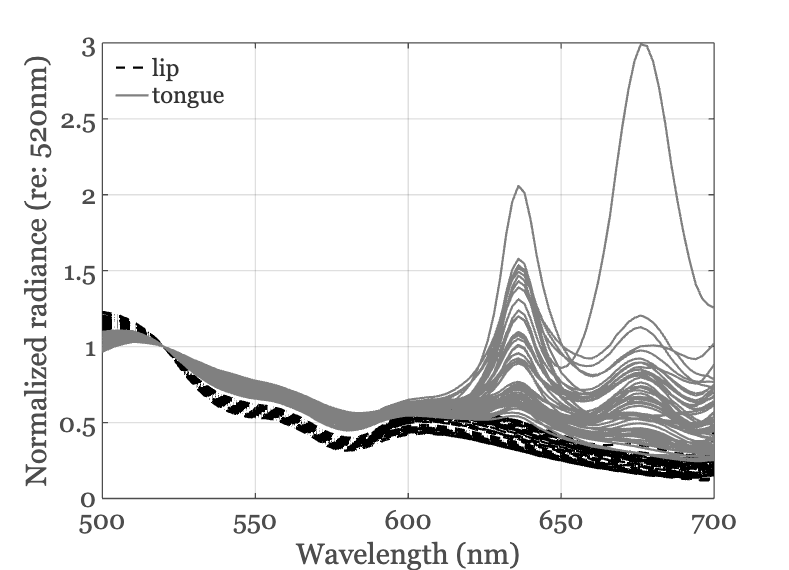

tongueData = [];
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tmp  = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);
    tongueData = cat(2,tongueData,tmp);
end

lipData = [];
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);
    tmp  = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);   
    lipData = cat(2,lipData,tmp);
end 

ieFigure; 
hA = plot(wave,lipData,'k--','LineWidth',2); hold on;
hB = plot(wave,tongueData,'Color',[1 1 1]*0.5,'LineWidth',2);
grid on; 
xlabel('Wavelength (nm)'); ylabel('Normalized radiance (re: 520nm)');
legend([hA(1),hB(1)],{'lip','tongue'},'Location','northwest');
set(gca,'ylim',[0 3],'Fontsize',24);
fname = fullfile(oeTongueLipRootPath,'figures','Figure4A.svg');
print(gcf,fname,'-dsvg');

% exportgraphics(gcf,'figure4A.png','Resolution',150);

### 450 nm excitation light

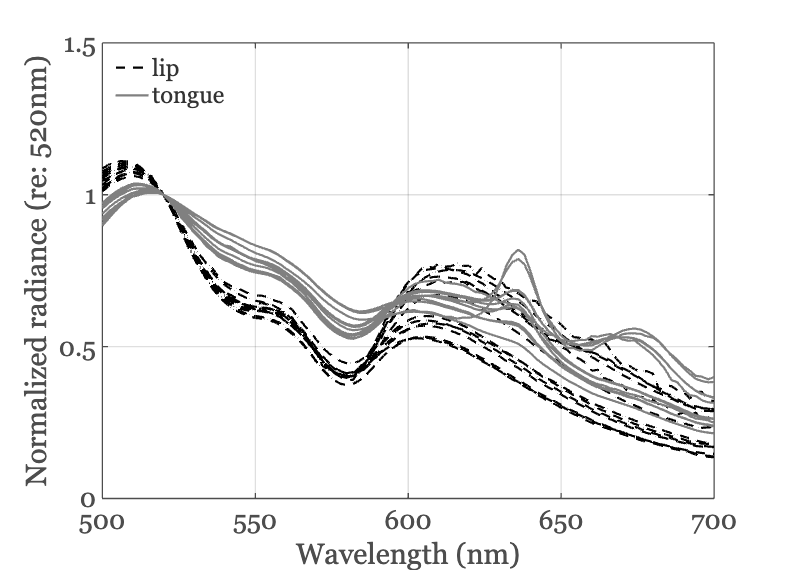

tongueData450 = [];
for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',450);
    tmp  = oeReadFiles(files450,'normalized wave',normWave,'wave',wave); 
    tongueData450 = cat(2,tongueData450,tmp);
end

lipData450 = [];
for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',450);
    tmp  = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);       
    lipData450 = cat(2,lipData450,tmp);
end 

ieFigure; 
hA = plot(wave,lipData450,'k--','LineWidth',2); hold on;
hB = plot(wave,tongueData450,'Color',[1 1 1]*0.5,'LineWidth',2);
grid on; 
xlabel('Wavelength (nm)'); ylabel('Normalized radiance (re: 520nm)');
set(gca,'ylim',[0 1.5],'Fontsize',24);
lgn = legend([hA(1),hB(1)],{'lip','tongue'},'Location','northwest');
fname = fullfile(oeTongueLipRootPath,'figures','Figure4B.svg');
print(gcf,fname,'-dsvg');

% exportgraphics(gcf,'figure4B.png','Resolution',150);

## A reviewer asked us to explore the remaining variation after normalization

Some of the remaining variation (after normalizing for the light level), is due to subject differences.  Here are the means for the four different subjects over the wavelength range of interest.

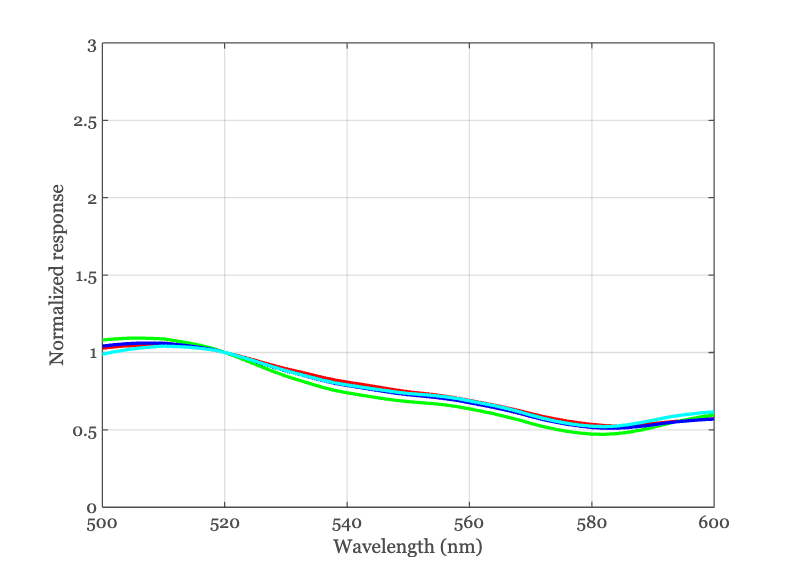


ieFigure; 
c = {'r','g','b','c'};
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tmp  = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);
    plot(wave,mean(tmp,2),[c{ii},'-'],'LineWidth',3); grid on; hold on;
    set(gca,'xlim',[500 600],'ylim',[0 3]);
end
xlabel('Wavelength (nm)');
ylabel('Normalized response');

## Fluorescence  dependence on current, after normalization (tongue)

There is no remaining dependence.

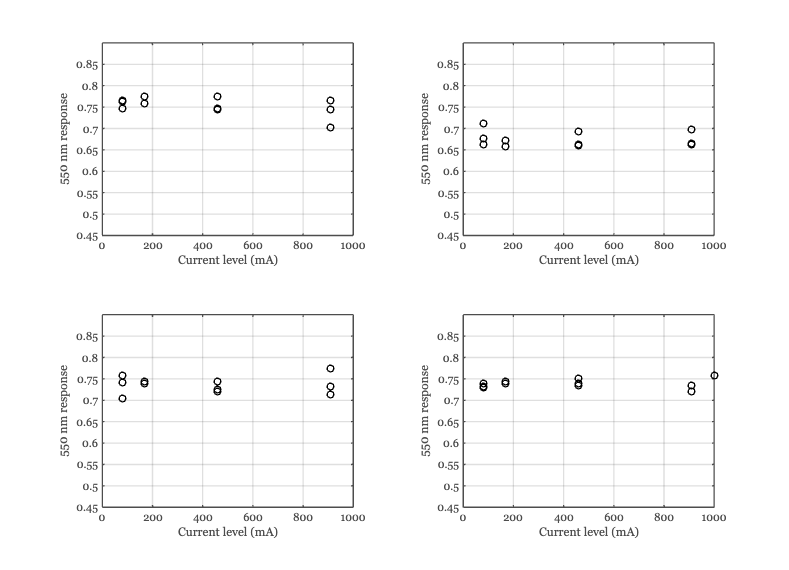

ieFigure; 
tiledlayout(2,2);
for ii=1:numel(subjects)
    [files415, tRows] = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    eLevelValues = tRows.elevel;
    
    nFiles = numel(files415);
    thisWave = 550;
    idxWave = find(wave==thisWave);
    thisResponse = zeros(nFiles,1);
    for jj = 1:nFiles        
        tmp = oeReadFiles(files415(jj),'normalized wave',normWave,'wave',wave);
        thisResponse(jj) = tmp(idxWave);
    end
    nexttile;
    plot(eLevelValues,thisResponse,'ko'); grid on;
    set(gca,'ylim',[0.45 0.90])
    xlabel('Current level (mA)'); ylabel(sprintf('%d nm response',thisWave));
end

## Now the lip

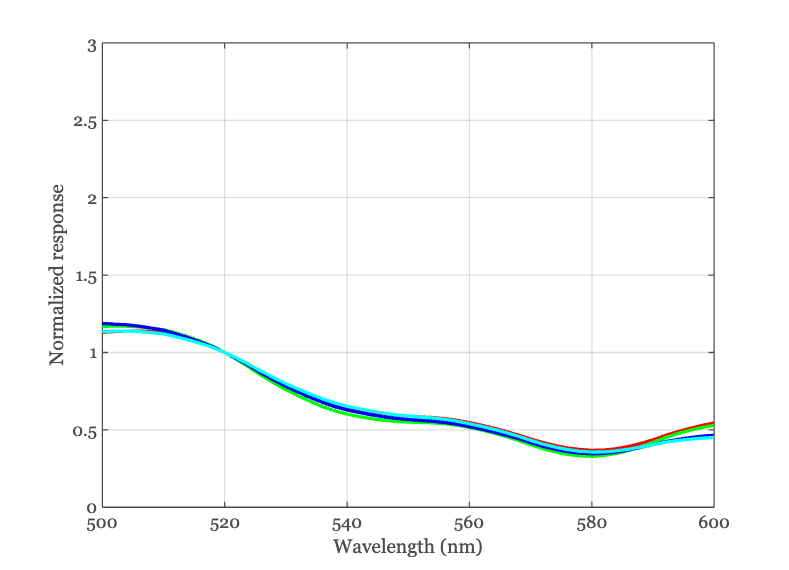

ieFigure; 
c = {'r','g','b','c'};
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tmp  = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);
    plot(wave,mean(tmp,2),[c{ii},'-'],'LineWidth',3); grid on; hold on;
    set(gca,'xlim',[500 600],'ylim',[0 3]);
end
xlabel('Wavelength (nm)');
ylabel('Normalized response');

## Fluorescence  dependence on current, after normalization (lip)

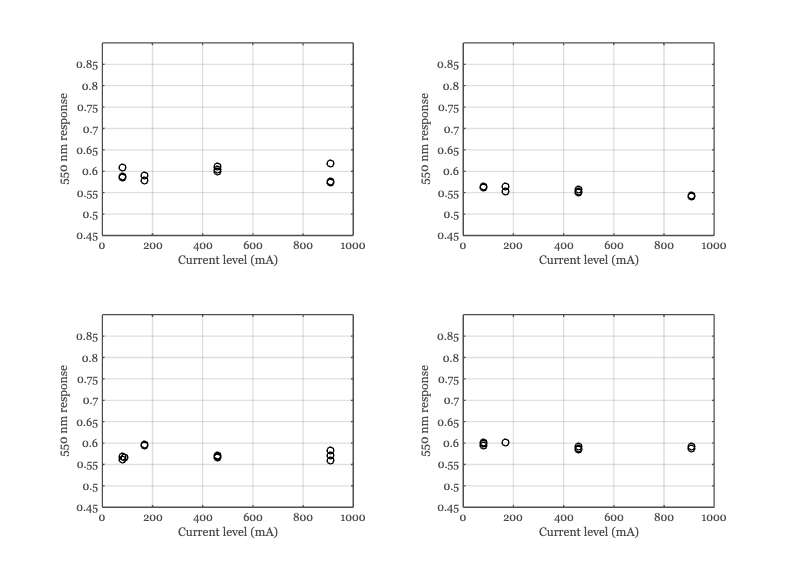

ieFigure; 
tiledlayout(2,2);
for ii=1:numel(subjects)
    [files415, tRows] = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    eLevelValues = tRows.elevel;
    
    nFiles = numel(files415);
    thisWave = 550;
    idxWave = find(wave==thisWave);
    thisResponse = zeros(nFiles,1);
    for jj = 1:nFiles        
        tmp = oeReadFiles(files415(jj),'normalized wave',normWave,'wave',wave);
        thisResponse(jj) = tmp(idxWave);
    end
    nexttile;
    plot(eLevelValues,thisResponse,'ko'); grid on;
    set(gca,'ylim',[0.45 0.90])
    xlabel('Current level (mA)'); ylabel(sprintf('%d nm response',thisWave));
end